data = load("Logi\pola\free_flight_1.mat");
Second_try = data.LOG00006_BFL;

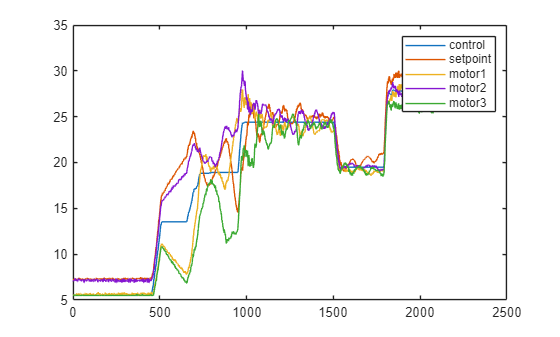

start = 144;
acc = Second_try.Var29(start:end)/2048;
acc_x = Second_try.Var27(start:end)/2048;
acc_y = Second_try.Var28(start:end)/2048;
control = Second_try.Var15(start:end);
setpt = 5.5 + (Second_try.Var19(start:end) / 1000) * (100 - 5.5);
eng_1 = (Second_try.Var30(start:end) - 48) / (2047 - 48) * 100;
eng_2 = (Second_try.Var31(start:end) - 48) / (2047 - 48) * 100;
eng_3 = (Second_try.Var32(start:end) - 48) / (2047 - 48) * 100;
eng_4 = (Second_try.Var33(start:end) - 48) / (2047 - 48) * 100;

eng_sum = (eng_1 + eng_2 + eng_3 + eng_4)/4;
% plot(control)
plot(setpt)
hold on
plot(eng_1)
plot(eng_2)
plot(eng_3)
plot(eng_4)
hold off
legend("control", "setpoint", "motor1", "motor2", "motor3", "motor4")

control_cal = (control-1000)*0.04

control_cal =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


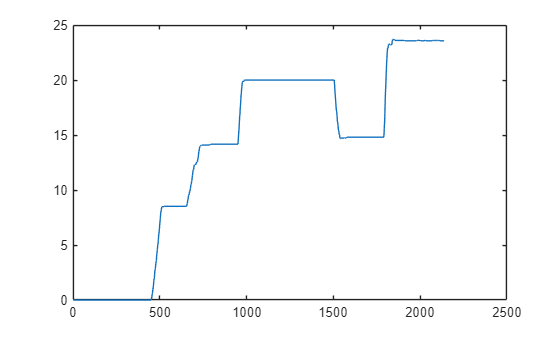

plot(control_cal)

t = 0:0.01:length(control_cal)/100-0.01

t =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


control_cal_normal = control_cal/100;

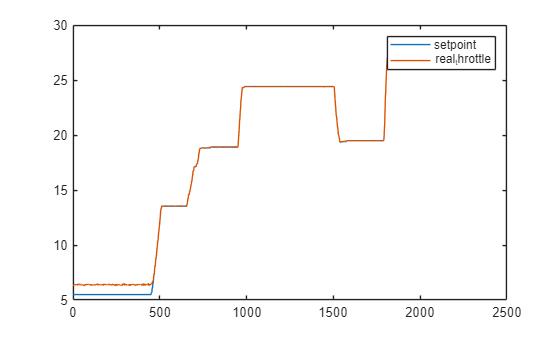

plot(setpt)
hold on
plot(eng_sum)
hold off
legend("setpoint", "real_throttle")

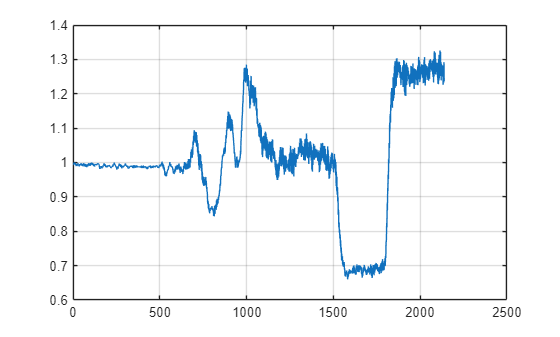

plot(acc)
grid on

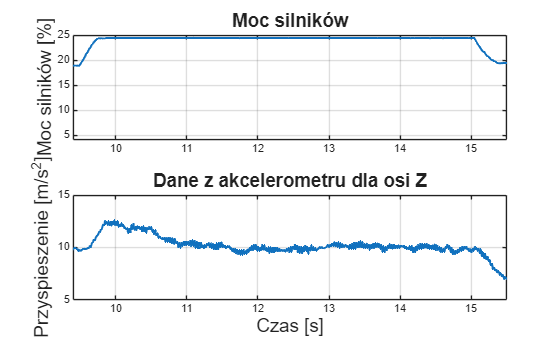

figure;

subplot(2,1,1)
plot(t, eng_sum, 'LineWidth', 1.5);
grid on;
ylabel('Moc silników [%]', 'FontSize', 14);
title('Moc silników', 'FontSize', 14);
xlim([9.4 15.5])
ylim([4 25])

subplot(2,1,2)
plot(t, acc*9.81, 'LineWidth', 1.5);
grid on;
xlabel('Czas [s]', 'FontSize', 14);
ylabel('Przyspieszenie [m/s^2]', 'FontSize', 14);
title('Dane z akcelerometru dla osi Z', 'FontSize', 14);
xlim([9.4 15.5])
ylim([5 15])